# Seguimiento de una consigna constante

Vamos a emplear el método visto en clase para seguir una consigna constante. Recordar que este método tiene el problema de que necesita un modelo perfecto del sistema. Vamos a emplear nuestro sistema de ejemplos anteriores.

Controlable y observable:


$$$A_c =\pmatrix{1&2&0 \cr
-2&3&0\cr
1&0&-2}, \ B = \pmatrix{1& 2\cr
1&0\cr
0&0}$$



$$C_0 = \pmatrix{1& 2& 1}$$


Ac = [1 2 0; -2 3 0; 1 0 -2];
B = [1 2;1 0;0 0];
Co = [1 2 1];

Vamos a suponer en primer lugar que el sistema admite realimentación directa de estados, esto el lo mismo que suponer que tenemos una salida $y =I_{n\times n}X$ (Supuesto que los estados son directamente observables).

Podemos calcular una ganacia para estabilizar el sistema, mediante cualquiera de los métodos descritos en controlabilidad, aquí vamos a emplear directamente place,

lambda = [-3 -4 -5]; %posicion deseada de los polos
K = place(Ac,B,lambda)

K =    -2.0000    8.0000   -0.0000
    4.0000   -3.0000    1.0000


Para que sea posible llevar el sistema a valores arbitrarios necesitamos poder construir una ganancia $F =(C(BK-A)^{-1}B)^{-1}$ En nuestro caso, la matriz $F^{-1} =C_{1\times3}{(BK-A)_{3\times 3}^{-1}B_{3\times2}$ No es invertible, de hecho, solo podrá serlo si coinciden el número de entradas con el de salidas. 

Si $BK-A$ es invertible, podemos todavía intentar un apaño


$$Bu^* =(BK- A)x_d \Rightarrow Cx_d = C(Bk-A)^{-1}Bu^*\\
y_{d(m\times1)} = (C(BK-A)^{-1}B)_{m\times k}u^*_{k\times 1}$$


Si $k>m$, podemos ajustar las entradas, de modo que obtengamos la salida, si $k<m$ lo mas probable es que no podamos hacer nada. En nuestro caso, tenemos dos entradas y una salida, podemos dar a una un valor arbitrario, por ejemplo $0$ y calcular cuanto debe valor la otra entrada en funcion de $y_d$

Vamos a construir una función que lo haga para nuestro caso (ver al final de Archivo)

Podemos ahora montar nuestro sistema realimentado con

valor de salida yd

yd = 12

yd = 12

Creamos una función específica para llevar a cabo la integral (solución del sistema)

ustr = u_estrella(Co,Ac,B,K,yd)

ustr =          0
   24.0000


sys = @(t,x)sistema_lineal_cs(t,x,K,ustr,Ac,B);
tf = 10;
x0 = [1;-3;2];
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0)%,opciones);

t =          0
    0.0013
    0.0026
    0.0039
    0.0052
    0.0116
    0.0180
    0.0245
    0.0309
    0.0631


x =     1.0000   -3.0000    2.0000
    1.0501   -2.9807    1.9962
    1.0999   -2.9616    1.9924
    1.1493   -2.9426    1.9887
    1.1985   -2.9237    1.9851
    1.4397   -2.8310    1.9682
    1.6734   -2.7413    1.9529
    1.8999   -2.6545    1.9394
    2.1195   -2.5703    1.9274
    3.1189   -2.1879    1.8894


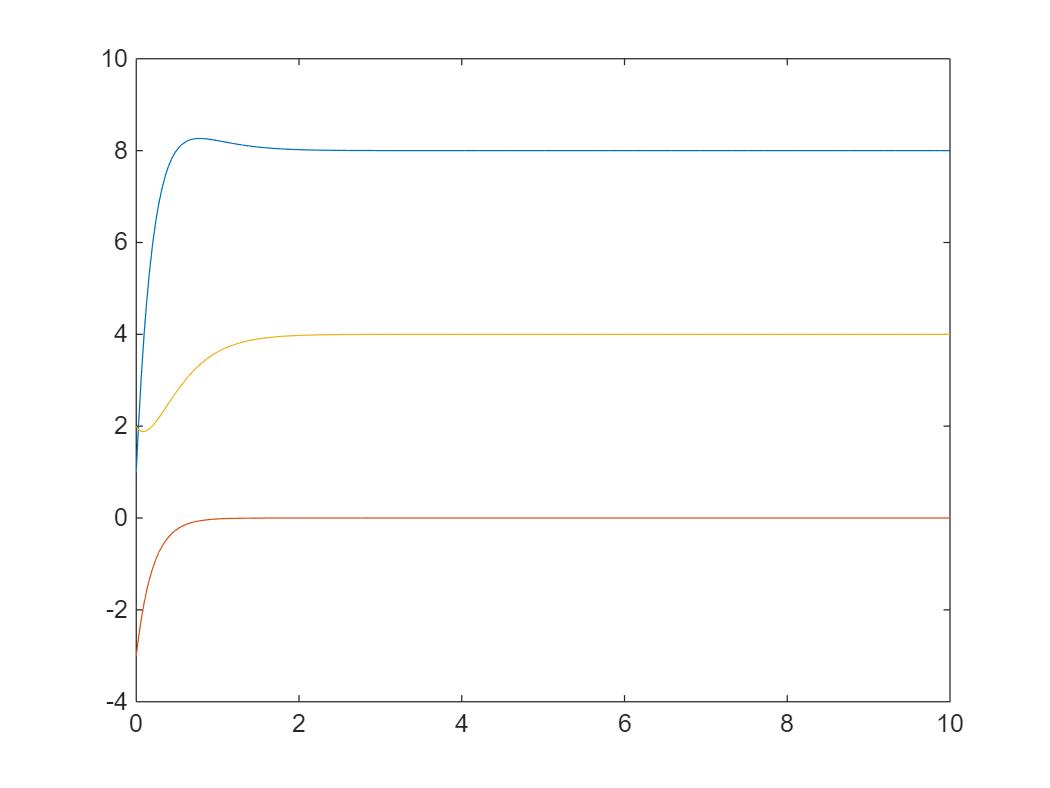

figure(1)
plot(t,x)

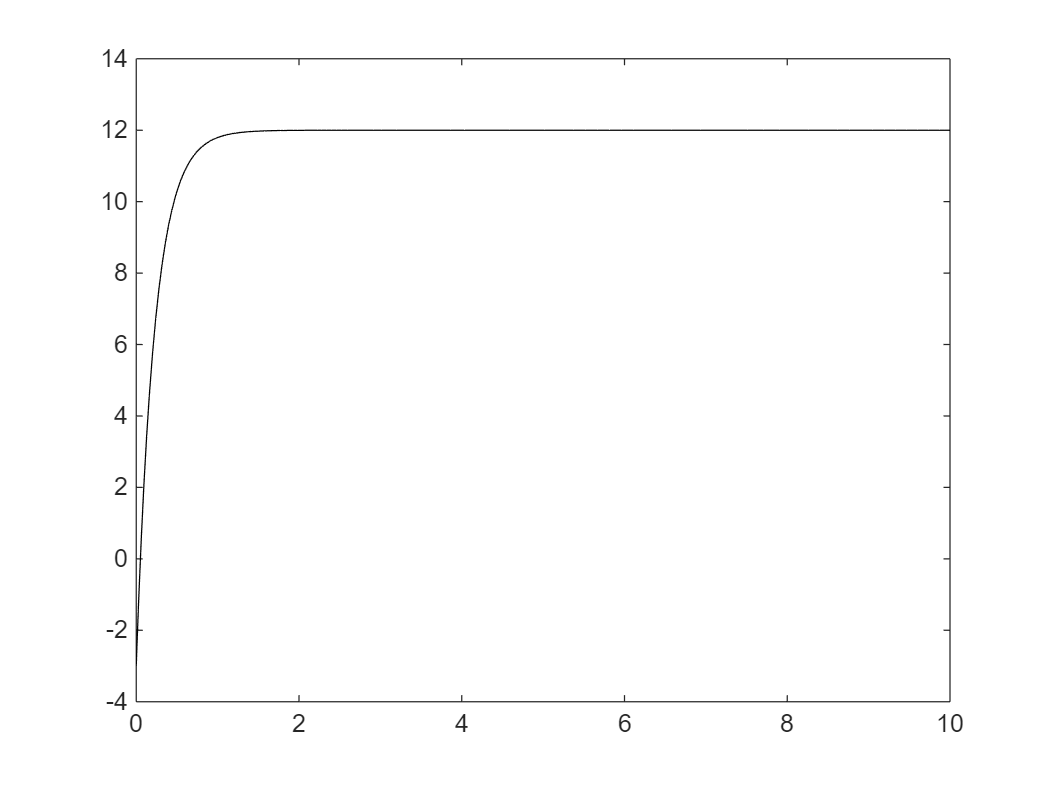

plot(t,Co*x','k')

Podemos reconstruir el ejemplo para ver el caso en que coinciden el número de entradas y salidas, y se puede calcular $F =(C(BK-A)^{-1}B)^{-1}$

Mantenemos los valores de A y B y construimos una nueva $C=\pmatrix{1&0&0 \cr 0&1&0 }$ es decir consideramos que se pueden medir directamente los dos primeros estados, Calculamos F,

C =[1 0 0;0 1 0]

C =      1     0     0
     0     1     0


F = (C*(B*K-Ac)^-1*B)^-1

F =     0.0000    5.0000
    3.0000   -2.5000


Elegimos unos valores de entrada que la salida debe seguir

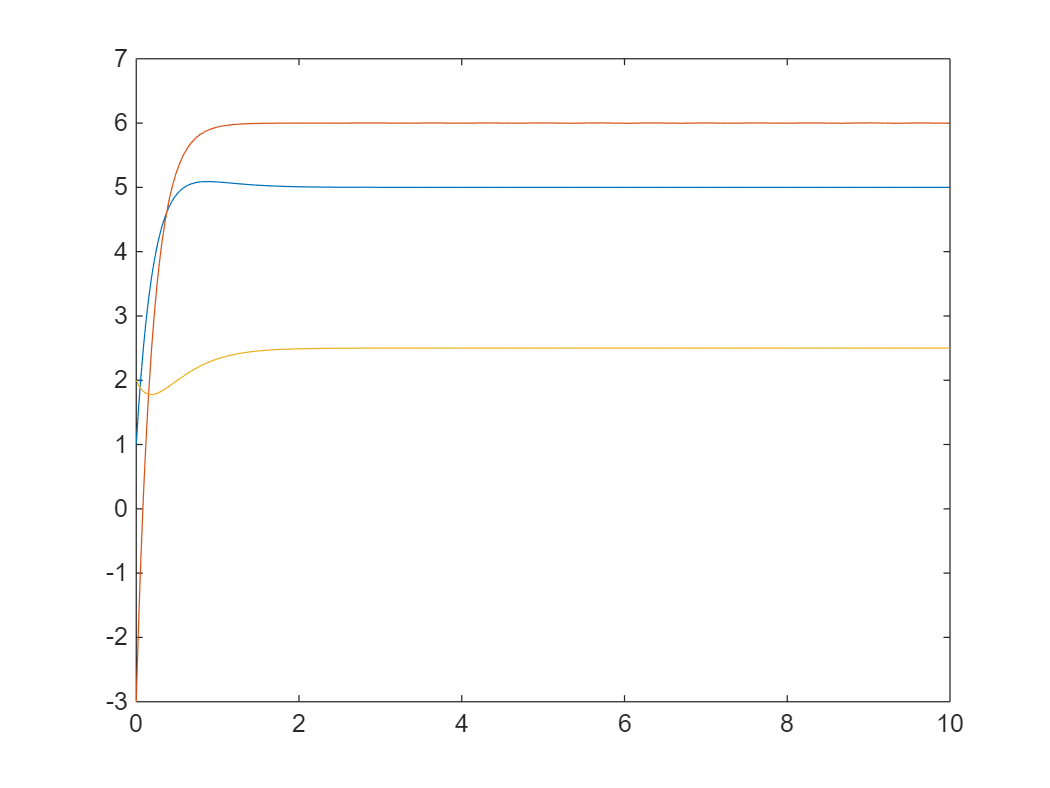

yd = [5;6];
sys = @(t,x)sistema_lineal_F(t,x,yd,K,F,Ac,B);
tf = 10;
x0 = [1;-3;2];
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(2)
plot(t,x)

function ustr = u_estrella(C,A,B,K,yd)
%la función solo sirve para sistemas 
% que tengan dos entradas y una salida XP
aux = C*(B*K-A)^-1*B; %si A no es invertible se acabó la fiesta
%Ajustamos la salida deseada a la segunda
%componente de la entrada

ustr =[0;yd/aux(2)];
end
function xdot = sistema_lineal_cs(t,x,K,ustr,A,B)
%modificamos el sistema lineal para ponerlo en modo realimentación
u = -K*x;
xdot = A*x+B*(u+ustr);
end

function xdot = sistema_lineal_F(t,x,yd,K,F,A,B)
%modificamos el sistema lineal para ponerlo en modo realimentación
u = -K*x+F*yd;
xdot = A*x+B*u;
end
